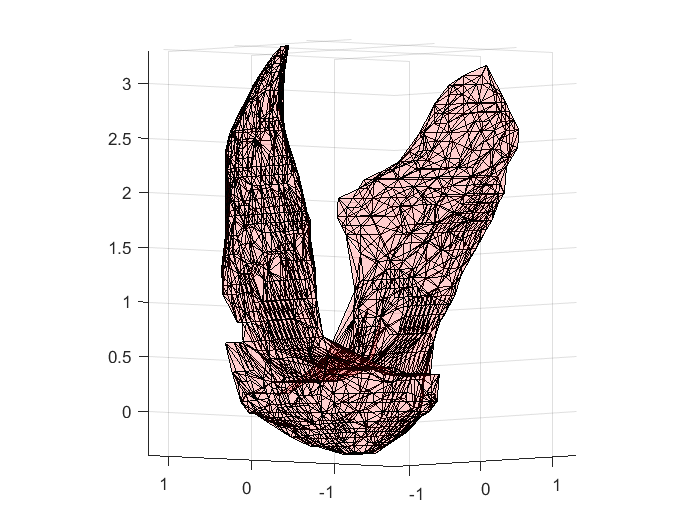

%fix the visual hull
meshPoints = singleObjData.v;

bounds = boundary(meshPoints(:,1),meshPoints(:,2),meshPoints(:,3),0.9);

trisurf(bounds,meshPoints(:,1),meshPoints(:,2),meshPoints(:,3),'Facecolor','red','FaceAlpha',0.1)
axis equal

uniqueIndices = unique([unique(bounds(:,1));unique(bounds(:,2));unique(bounds(:,3))]);

reducedPoints = meshPoints(uniqueIndices,:);

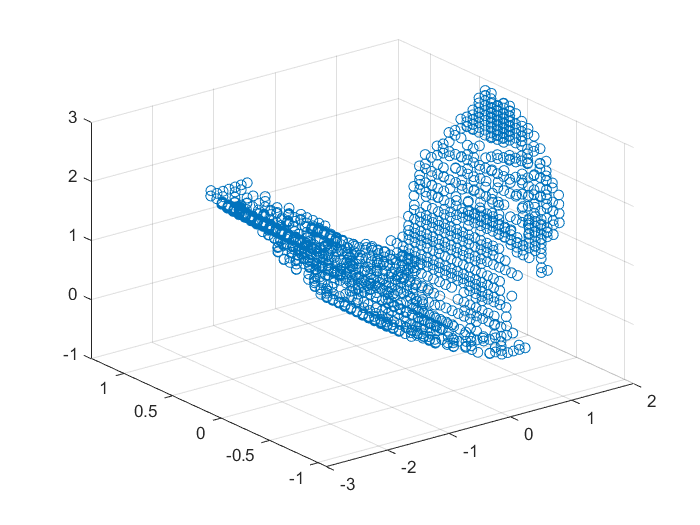


newPointCloud = scatter3(reducedPoints(:,1),reducedPoints(:,2),reducedPoints(:,3));

%Fix the data
directoryInfoMesh = dir('C:\Users\yohan\Downloads\ConvexHullCalibration-20220126T154827Z-001\ConvexHullCalibration');
 
for i = 3:size(directoryInfoMesh,1) - 2
   
    %get mesh
    objData = readObj(fullfile(directoryInfoMesh(i).folder,directoryInfoMesh(i).name));
    meshPoints = objData.v;
    
    %get bounds
    bounds = boundary(meshPoints(:,1),meshPoints(:,2),meshPoints(:,3),0.9);
    trisurf(bounds,meshPoints(:,1),meshPoints(:,2),meshPoints(:,3),'Facecolor','red','FaceAlpha',0.1)
    title(string(i))
    axis equal
    
    %get indices
    uniqueIndices = unique([unique(bounds(:,1));unique(bounds(:,2));unique(bounds(:,3))]);
    reducedPoints = meshPoints(uniqueIndices,:);
    pause(0.1)
end